clearvars;
%measurement settings
format shortG
xmin = -5;
xmax = 5;
ymin = -5;
ymax = 5;
zmin = 0;
zmax = 5;
xint = 0.5;
yint = 0.5;
zint = 0.5;
xtotal = ((xmax-xmin)/xint + 1);
ytotal = ((ymax-ymin)/yint + 1);
ztotal = ((zmax-zmin)/zint + 1);
%datasize = xtotal*ytotal*ztotal;
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 3/16*25.4 %mm

diameter =        4.7625


height = 1/8*25.4 %mm

height =         3.175


Br_max = 12100*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 35; %mm

%this is for averaging the measurements at a specific location
% location = [];
% z = zmin;
% dataavg = [];
% 
% for k = 1:ztotal
%     zstr = sprintf('%.1f', z);
%     y = ymin;
% 
%     for j = 1:ytotal
%         ystr = sprintf('%.1f', y);
%         x = xmin;
% 
%         for i = 1:xtotal
% 
%             xstr = sprintf('%.1f', x);
%             filename = append('PIM05242023_measurement\',xstr,'_',ystr,'_',zstr,'.data');
%             test = importdata(filename);
%             
%             bx1 = test.data(1:99,6);
%             by1 = test.data(1:99,7);
%             bz1 = test.data(1:99,8);
% 
%             bx2 = test.data(100:199,6);
%             by2 = test.data(100:199,7);
%             bz2 = test.data(100:199,8);
% 
%             bx3 = test.data(200:299,6);
%             by3 = test.data(200:299,7);
%             bz3 = test.data(200:299,8);
%             
%             bx4 = test.data(300:399,6);
%             by4 = test.data(300:399,7);
%             bz4 = test.data(300:399,8);
%             dataavg = [dataavg 
%                 [mean(bx1) mean(by1) mean(bz1) mean(bx2) mean(by2) mean(bz2) mean(bx3) mean(by3) mean(bz3) mean(bx4) mean(by4) mean(bz4)]];
%             location = [location
%                 [x y z]];
%            
%             x = x + xint;
%         end
%         y = y + yint;
%     end
%     z = z + zint;
% end

location = importdata('PIM05242023_locations.txt');
dataavg = importdata('PIM05242023_averages.txt');

sen1 = dataavg(:,1:3) %bottom left sensor

sen1 =     -0.029751     0.042247    -0.021367
     -0.02966     0.042259    -0.021404
    -0.029426     0.042326     -0.02141
    -0.028947      0.04242    -0.021405
    -0.028407      0.04263    -0.021423
    -0.027814     0.042552    -0.021458
     -0.02712     0.042675    -0.021418
    -0.026361     0.042771    -0.021396
    -0.025434     0.042839    -0.021316
    -0.024444     0.042956    -0.021247


sen2 = dataavg(:,4:6) %bottom right sensor

sen2 =     -0.021461     0.026952   -0.0036372
    -0.021551     0.027028   -0.0036064
    -0.021723     0.027162   -0.0036261
    -0.021821     0.027332   -0.0035767
    -0.021948     0.027792   -0.0034874
    -0.022147     0.027813   -0.0034207
    -0.022362     0.028132   -0.0032494
    -0.022552     0.028563   -0.0031138
    -0.022717     0.029014    -0.002916
    -0.023074     0.029364   -0.0026575


sen3 = dataavg(:,7:9) %top left sensor (the magnet is centered above this sensor)

sen3 =     -0.029105    -0.031984      0.13028
    -0.028747    -0.032027      0.13055
    -0.027813    -0.032108      0.13097
    -0.026347    -0.032162      0.13156
    -0.024611    -0.032084       0.1323
      -0.0227    -0.032303      0.13301
    -0.020367    -0.032342      0.13387
    -0.017842    -0.032374      0.13456
    -0.014913    -0.032389      0.13519
     -0.01156    -0.032504      0.13565


sen4 = dataavg(:,10:12) %top right sensor

sen4 =     -0.046335    0.0031516    -0.017987
     -0.04652    0.0031681    -0.017935
    -0.046883     0.003019     -0.01774
    -0.047278    0.0029793    -0.017418
    -0.047816    0.0028691    -0.017085
    -0.048352    0.0025812    -0.016653
    -0.049033    0.0024581    -0.016051
    -0.049669    0.0022786    -0.015453
    -0.050426    0.0021394    -0.014799
    -0.051363    0.0017896    -0.013897


X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 1], 4851, 1);
expectB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

expectB =      0.049256     0.049256      0.22517
     0.044746     0.049718      0.22773
     0.040109     0.050137      0.23005
     0.035357      0.05051      0.23213
     0.030502     0.050836      0.23394
     0.025557     0.051115      0.23549
     0.020538     0.051345      0.23677
     0.015457     0.051524      0.23777
     0.010331     0.051653      0.23849
     0.005173      0.05173      0.23892


testB = 2*sen3

testB =      -0.05821    -0.063969      0.26056
    -0.057493    -0.064055      0.26109
    -0.055627    -0.064215      0.26194
    -0.052695    -0.064324      0.26311
    -0.049223    -0.064168      0.26461
    -0.045401    -0.064606      0.26602
    -0.040735    -0.064683      0.26774
    -0.035683    -0.064748      0.26913
    -0.029826    -0.064778      0.27038
    -0.023121    -0.065007      0.27131


%fitting for the angle, the sensor is at (0,0,0)
ind = 10;
d_data = sen3;
loc = location + [0 0 35];
datasize = length(sen3);
dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
nonlcon = @con;
        
x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1,-1];
ub = [1,1,1];
[angle, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


angle =       0.64179     -0.17556      0.74651


fval =        25.055


fval/datasize

ans =     0.0051649


sqrt(sum(angle.^2))

ans =             1


%fitting for the location using the angle from above, the sensor is at (0,0,0)
fixapreds = [];
fixafvalues = [];
for t = 1:length(sen3)
    B_data = sen3(t,:);
    costfun = @(v)loccost(v, angle, B_data, B_t);
    nonlcon = @con;

    x0 = [-5,-5,35];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-20, -20, 30];
    ub = [20, 20, 60];
    [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
    fixapreds = [fixapreds; locs];
    fixafvalues = [fixafvalues; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

%fitting for the angle with 2x measured B, the sensor is at (0,0,0)
ind = 10;
d_data = testB;
loc = location + [0 0 35];
datasize = length(sen3);
dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
nonlcon = @con;
        
x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1,-1];
ub = [1,1,1];
[angle, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


angle =      0.080677    -0.022068       0.9965


fval =        4.9894


fval/datasize

ans =     0.0010285


sqrt(sum(angle.^2))

ans =             1


X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([angle], 4851, 1);
faB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

faB =      0.039845     0.052136      0.22727
     0.035208     0.052558      0.22945
     0.030458     0.052933      0.23138
     0.025609     0.053261      0.23305
     0.020674      0.05354      0.23446
     0.015667     0.053768       0.2356
     0.010602     0.053946      0.23647
    0.0054928     0.054071      0.23705
   0.00035581     0.054144      0.23735
   -0.0047942     0.054164      0.23736


expectB

expectB =      0.049256     0.049256      0.22517
     0.044746     0.049718      0.22773
     0.040109     0.050137      0.23005
     0.035357      0.05051      0.23213
     0.030502     0.050836      0.23394
     0.025557     0.051115      0.23549
     0.020538     0.051345      0.23677
     0.015457     0.051524      0.23777
     0.010331     0.051653      0.23849
     0.005173      0.05173      0.23892


fabdiff = expectB - faB

fabdiff =      0.009411   -0.0028797   -0.0020978
    0.0095387   -0.0028394   -0.0017148
     0.009651   -0.0027966   -0.0013233
    0.0097475   -0.0027512  -0.00092443
    0.0098274   -0.0027035  -0.00051918
    0.0098905   -0.0026535  -0.00010871
    0.0099362   -0.0026014   0.00030581
    0.0099644   -0.0025473   0.00072316
    0.0099748   -0.0024914    0.0011421
    0.0099672   -0.0024339    0.0015614


max(fabdiff)

ans =      0.016288   -0.0017443     0.010253


%fitting for the location using the angle from above with 2x measured B, the sensor is at (0,0,0)
fixapreds = [];
fixafvalues = [];
for t = 1:length(sen3)
    B_data = sen3(t,:);
    costfun = @(v)loccost(v, angle, B_data, B_t);
    nonlcon = @con;

    x0 = [-5,-5,35];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-20, -20, 30];
    ub = [20, 20, 60];
    [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
    fixapreds = [fixapreds; locs];
    fixafvalues = [fixafvalues; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([angle], 4851, 1);
expectB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

expectB =      0.039845     0.052136      0.22727
     0.035208     0.052558      0.22945
     0.030458     0.052933      0.23138
     0.025609     0.053261      0.23305
     0.020674      0.05354      0.23446
     0.015667     0.053768       0.2356
     0.010602     0.053946      0.23647
    0.0054928     0.054071      0.23705
   0.00035581     0.054144      0.23735
   -0.0047942     0.054164      0.23736


fixapreds

fixapreds =       -4.8821      -6.9761         41.8
      -4.8028      -6.9787       41.794
      -4.6087      -6.9932         41.8
      -4.2901      -6.9892        41.82
      -3.9132      -6.9495       41.842
      -3.5032      -6.9694        41.85
      -3.0047      -6.9464       41.862
      -2.4819      -6.9282       41.887
      -1.8716      -6.9046       41.914
      -1.1975      -6.9251       41.941


fixafvalues

fixafvalues =    1.8287e-08
   1.0149e-08
   3.3743e-09
   2.4393e-09
   1.6323e-09
   1.6691e-09
     3.26e-10
   1.5926e-09
   2.8195e-09
   2.7294e-09


fixadiff = fixapreds - loc

fixadiff =       0.11788      -1.9761       6.8001
      -0.3028      -1.9787        6.794
     -0.60871      -1.9932       6.7998
     -0.79006      -1.9892       6.8199
      -0.9132      -1.9495       6.8421
      -1.0032      -1.9694       6.8502
      -1.0047      -1.9464        6.862
     -0.98186      -1.9282        6.887
     -0.87156      -1.9046        6.914
     -0.69751      -1.9251       6.9412


max(fixadiff)

ans =       0.76766       3.0051        8.665


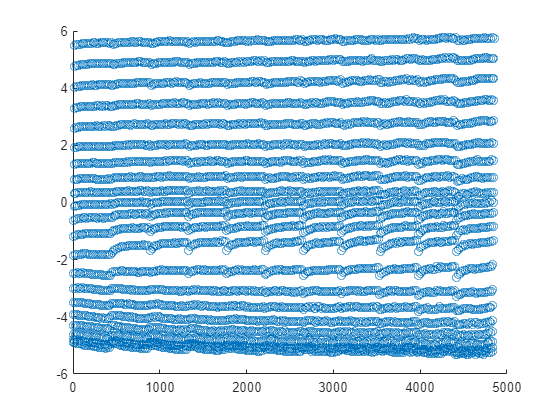

%predicted location using fixed angle
scatter(1:4851,fixapreds(:,1)) %x values

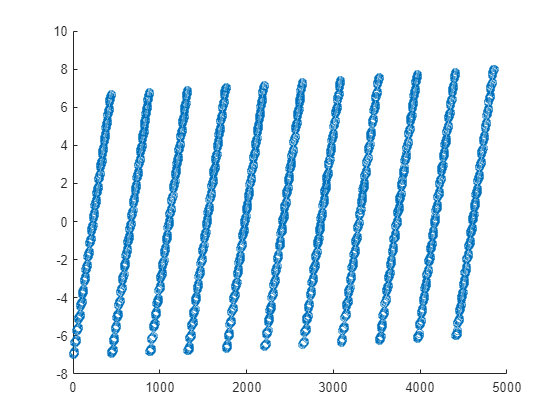

scatter(1:4851,fixapreds(:,2)) %y values

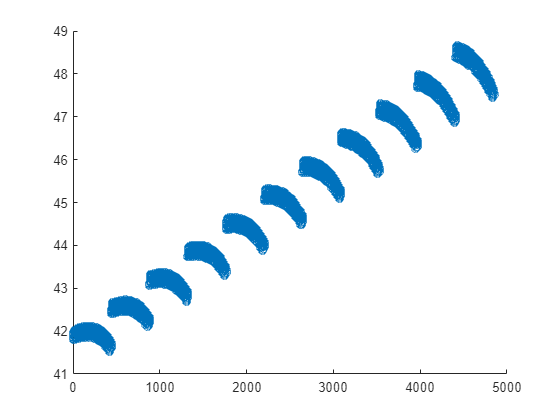

scatter(1:4851,fixapreds(:,3)) %z values

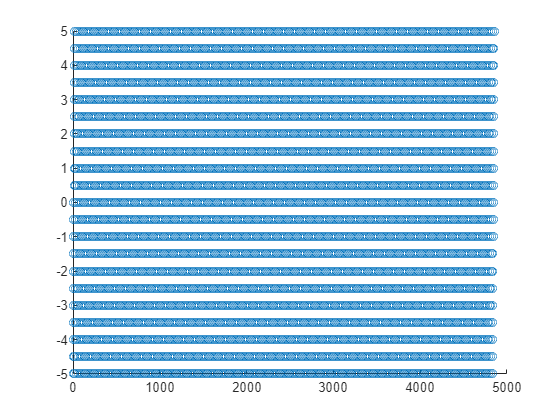

% scatter(1:4851,fixadiff(:,1))
% scatter(1:4851,fixadiff(:,2))
% scatter(1:4851,fixadiff(:,3))

%actual location of measurement
scatter(1:4851,loc(:,1))

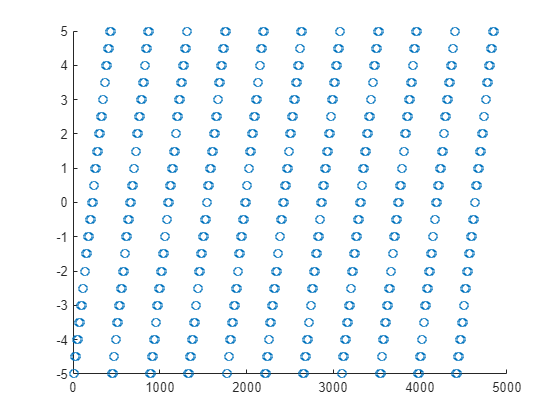

scatter(1:4851,loc(:,2))

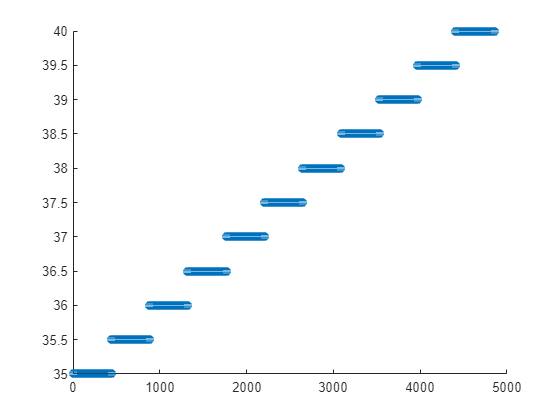

scatter(1:4851,loc(:,3))

testx = sen3 + [0.009 0 0]

testx =        -0.0201049088015669       -0.0319843310074673         0.130279593585506
       -0.0197467254253887       -0.0320274207369323         0.130546823356592
       -0.0188133186436528       -0.0321076019096585         0.130971905986045
       -0.0173474721508141       -0.0321620149345085          0.13155618802791
       -0.0156113355367854       -0.0320837923858489         0.132302546211287
       -0.0137003305178112       -0.0323032194883095         0.133007528461256
       -0.0113673644264904       -0.0323416574856164         0.133869506671563
       -0.0088415962786143       -0.0323740971967193         0.134563594075162
        -0.005913147264047       -0.0323890929122292         0.135190659811482
       -0.0025603501040519       -0.0325036724201249         0.135652833884196


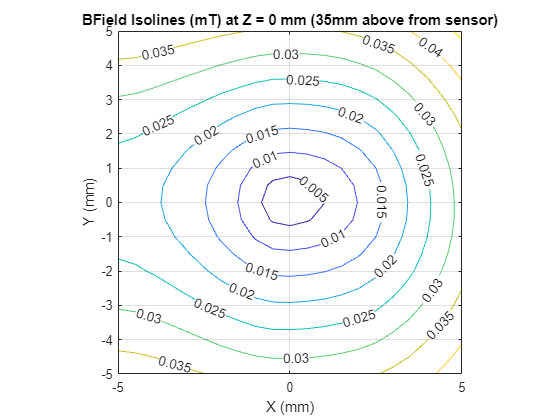

locavg = [location testx];
format longG
zzero = find(abs(locavg(:,3)-0) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;

axis image
grid on;
title('BField Isolines (mT) at Z = 0 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

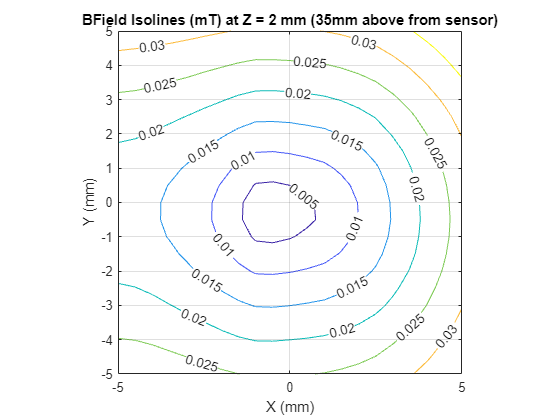

zzero = find(abs(locavg(:,3)-2) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
axis image
grid on;
title('BField Isolines (mT) at Z = 2 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

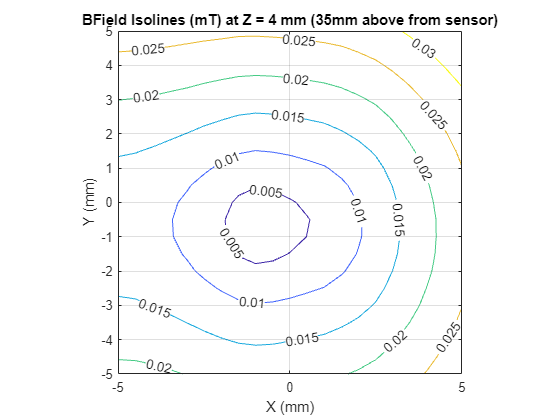

zzero = find(abs(locavg(:,3)-4) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
axis image
grid on;
title('BField Isolines (mT) at Z = 4 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

06/06/2023

Meeting Notes

Rotate all sensors and repeat measurement to see if the same stretching happens.

Satwik has circuit board design done and ordered

Sensors are 25mm apart

Maybe try multi sensor with fixed angle (180,000 points) 

Put together Pi and Screen

Stronger magnet, Satwik says he found N55 strength, [https://buymagnets.com/product/neodymium-disc-magnets-n55/](https://buymagnets.com/product/neodymium-disc-magnets-n55/)

Figure out what magnet to buy for next week, look for even stronger magnets

06/13/2023

Test the other N35 magnets for this stretching

check if printer motion is consistent in all three axes

try switching the order of the x and y axes in calibration

measure background

will need to solder sensors onto pcb, look for solder paste and a heat gun.

look for local reseller of bunting magnet, or a way to reduce shipping.

% %fitting for the angle and location, the sensor is at (0,0,0)
% preds = [];
% fvalues = [];
% for t = 1:length(sen3)
%     B_data = sen3(t,:);
%     costfun = @(v)bothcost(v, B_data, B_t);
%     nonlcon = @con;
% 
%     x0 = [0,0,0, -5,-5,35];
%     A = [];
%     b = [];
%     Aeq = [];
%     beq = [];
%     lb = [-1,-1,-1,-7, -7, 0];
%     ub = [1,1,1, 7, 7, 50];
%     [mins, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon);
%     preds = [preds; mins];
%     fvalues = [fvalues; fval];
% end

% anglepred = preds(:,1:3)
% locpred = preds(:,4:6)
% fvalues
% loc
% diff = locpred-loc
% max(diff)
% max(anglepred(:,1))
% max(anglepred(:,2))
% min(anglepred(:,3))

% %predicted location from fitting angle and location
% scatter(1:4851,locpred(:,1)) %x values
% scatter(1:4851,locpred(:,2)) %y values
% scatter(1:4851,locpred(:,3)) %z values
% % scatter(1:4851,fixadiff(:,1))
% % scatter(1:4851,fixadiff(:,2))
% % scatter(1:4851,fixadiff(:,3))
% 
% %actual location of measurement
% scatter(1:4851,loc(:,1))
% scatter(1:4851,loc(:,2))
% scatter(1:4851,loc(:,3))

% scatter(1:4851, sen3(:,1))
% hold on;
% grid on;
% xlim([0 100])
% hold off;
% scatter(1:4851, sen3(:,2))
% hold on;
% grid on;
% xlim([0 100])
% hold off;
% scatter(1:4851, sen3(:,3))
% hold on;
% grid on;
% xlim([0 100])
% hold off;

function a = anglecost(v, loc, B_data, B_t, datasize)
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t)
X1 = [-x(1) -x(2) -x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end